# Assignment 10

William Watkins, in collaboration with Addi Woodard and Sarah Foley

18 November, 2019

## Clear the workspace

clear all
close all
clc

## 1. 

Declare constants, retrieve values

global Constants nDLatDer E1
B747LatValues()

Calculate the Body Frame Dimensional Derivatives

DLatDer.v.Y = 0.5  * E1.rho * E1.u0 * E1.S * nDLatDer.Beta.Cy;              % [N*s/m]
DLatDer.v.L = 0.5  * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.Beta.Cl;       % [N/s]
DLatDer.v.N = 0.5  * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.Beta.Cn;       % [N/s]

DLatDer.p.Y = 0.25 * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.pHat.Cy;       % [N*s/rad]
DLatDer.p.L = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.pHat.Cl;   % [N*m*s/rad]
DLatDer.p.N = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.pHat.Cn;   % [N*m*s/rad]

DLatDer.r.Y = 0.25 * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.rHat.Cy;       % [N*s/rad]
DLatDer.r.L = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.rHat.Cl;   % [N*m*s/rad]
DLatDer.r.N = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.rHat.Cn;   % [N*m*s/rad]

% Values calculated above
disp(DLatDer.v)

    Y: -2.3096e+04
    L: -4.3928e+05
    N: 3.0563e+05



disp(DLatDer.p)

    Y: 0
    L: -1.5433e+07
    N: -1.9077e+06



disp(DLatDer.r)

    Y: 0
    L: 1.4238e+07
    N: -1.2805e+07



Calculate the Stability Frame Dimensional Derivatives, from (B.12, 7), page 356

StabDer.v.Y = DLatDer.v.Y;
StabDer.v.L = DLatDer.v.L * cos(E1.Xi) - DLatDer.v.N * sin(E1.Xi);
StabDer.v.N = DLatDer.v.N * cos(E1.Xi) + DLatDer.v.L * sin(E1.Xi);

StabDer.p.Y = DLatDer.p.Y * cos(E1.Xi) - DLatDer.r.Y * sin(E1.Xi);
StabDer.p.L = DLatDer.p.L * cos(E1.Xi)^2 - (DLatDer.r.L + DLatDer.p.N) * ...
    sin(E1.Xi) * cos(E1.Xi) + DLatDer.r.N * sin(E1.Xi)^2;
StabDer.p.N = DLatDer.p.N * cos(E1.Xi)^2 - (DLatDer.r.N - DLatDer.p.L) * ...
    sin(E1.Xi) * cos(E1.Xi) - DLatDer.r.L * sin(E1.Xi)^2;

StabDer.r.Y = DLatDer.r.Y * cos(E1.Xi) + DLatDer.p.Y * sin(E1.Xi);
StabDer.r.L = DLatDer.r.L * cos(E1.Xi)^2 - (DLatDer.r.N - DLatDer.p.L) * ...
    sin(E1.Xi) * cos(E1.Xi) - DLatDer.p.N * sin(E1.Xi)^2;
StabDer.r.N = DLatDer.r.N * cos(E1.Xi)^2 + (DLatDer.r.L + DLatDer.p.N) * ...
    sin(E1.Xi) * cos(E1.Xi) + DLatDer.p.L * sin(E1.Xi)^2;

Calculate primed moments of inertia from (4.9, 19), page 113

IPrime.x = (E1.Ix * E1.Iz - E1.Izx ^2) / E1.Iz;
IPrime.z = (E1.Ix * E1.Iz - E1.Izx ^2) / E1.Ix;
IPrime.zx = E1.Izx / (E1.Ix * E1.Iz - E1.Izx ^2);

## 2.

Create the lateral A matrix, (4.9,19), page 113

Alat = zeros(4, 4);

Alat(1, 1) = StabDer.v.Y / E1.m;
Alat(1, 2) = StabDer.p.Y / E1.m;
Alat(1, 3) = ((StabDer.r.Y / E1.m) - E1.u0);
Alat(1, 4) = Constants.g * cos(E1.theta0);

Alat(2, 1) = ((StabDer.v.L / IPrime.x) + IPrime.zx * StabDer.v.N);
Alat(2, 2) = ((StabDer.p.L / IPrime.x) + IPrime.zx * StabDer.p.N);
Alat(2, 3) = ((StabDer.r.L / IPrime.x) + IPrime.zx * StabDer.r.N);
Alat(2, 4) = 0;

Alat(3, 1) = (IPrime.zx * StabDer.v.L + (StabDer.v.N / IPrime.z));
Alat(3, 2) = (IPrime.zx * StabDer.p.L + (StabDer.p.N / IPrime.z));
Alat(3, 3) = (IPrime.zx * StabDer.r.L + (StabDer.r.N / IPrime.z));
Alat(3, 4) = 0;

Alat(4, 1) = 0;
Alat(4, 2) = 1;
Alat(4, 3) = tand(E1.theta0);
Alat(4, 4) = 0;

## 3.

Determine eigenvectors and eigenvalues of the lateral A matrix

[V, D] = eig(Alat); % returns a vector containing the eigenvectors, and a vector
% containing the eigenvalues along the diagonal
D = diag(D); % Eigenvalues are extracted from the diagonal
V

V =    0.9998 + 0.0000i   0.9998 + 0.0000i  -0.9894 + 0.0000i   0.9210 + 0.0000i
  -0.0094 + 0.0112i  -0.0094 - 0.0112i  -0.0881 + 0.0000i  -0.0020 + 0.0000i
   0.0005 - 0.0055i   0.0005 + 0.0055i   0.0029 + 0.0000i   0.0237 + 0.0000i
   0.0121 + 0.0094i   0.0121 - 0.0094i   0.1153 + 0.0000i   0.3889 + 0.0000i


D

D =   -0.0391 + 0.9565i
  -0.0391 - 0.9565i
  -0.7648 + 0.0000i
  -0.0051 + 0.0000i


Plot eigenvalues!

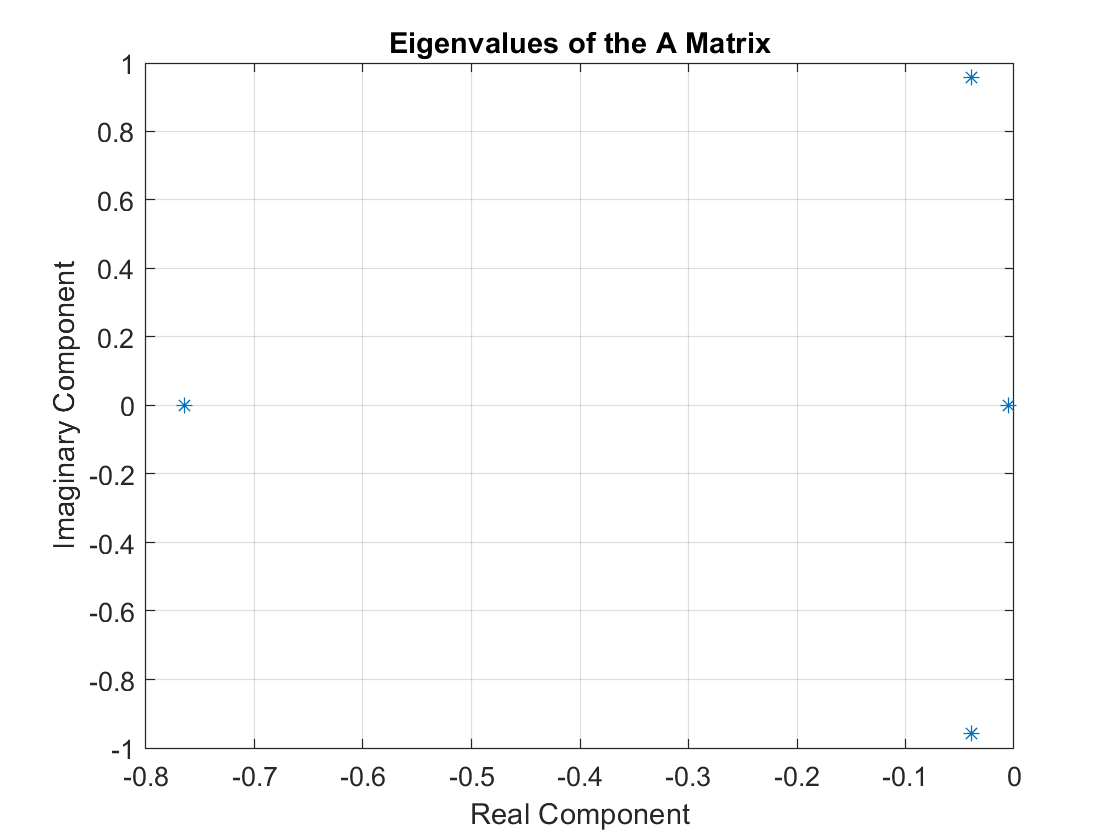

figure()
plot(D,'*')
hold on
title('Eigenvalues of the A Matrix')
grid on
xlabel('Real Component')
ylabel('Imaginary Component')
hold off

Looking at the eigenvalues, we can immediately identify the Dutch Roll mode as the only mode with complex eigenvalues.  We observe that the Roll mode is the more negative real eigenvalue, and finally the least negative eigenvalue is the Spiral Mode.

DutchRoll = D(1:2)

DutchRoll =   -0.0391 + 0.9565i
  -0.0391 - 0.9565i


Roll = D(3)

Roll = -0.7648

Spiral = D(4)

Spiral = -0.0051

We can then plot the responses from each eigenvalue

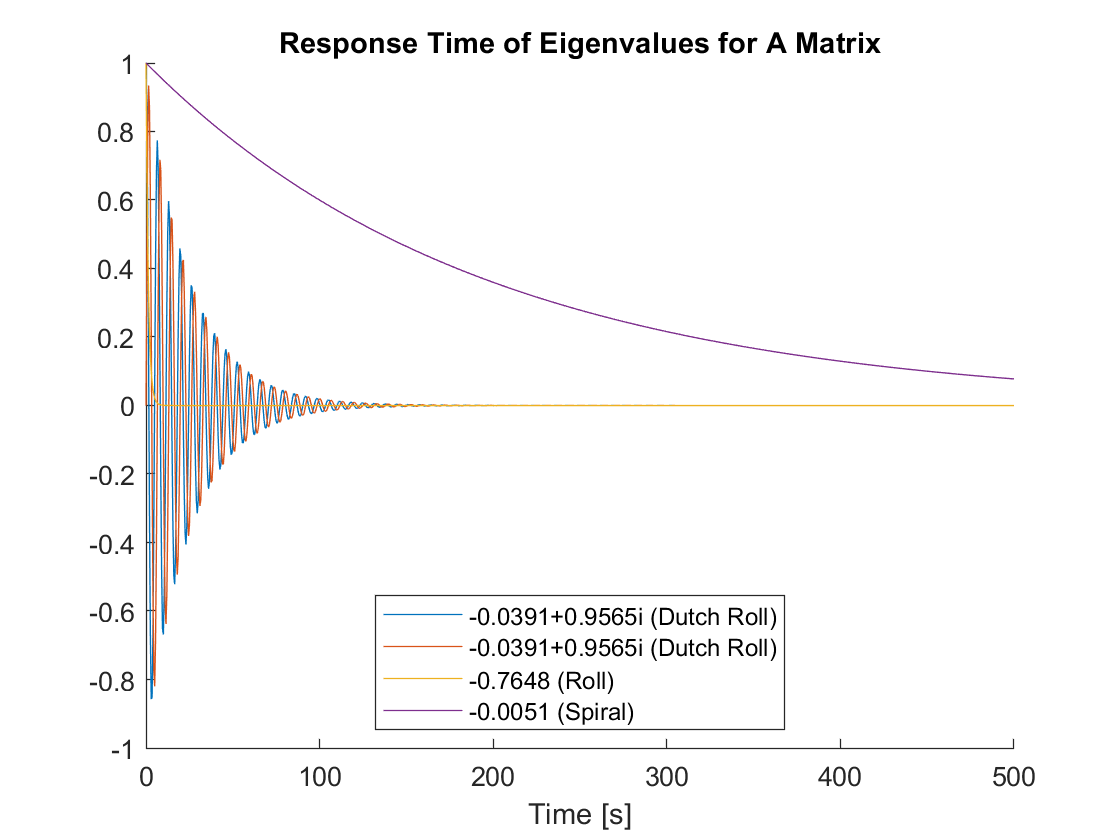

t = linspace(0,500, 1000);
figure()
hold on
y1 = exp(real(D(1) .* t)) .* cos(imag(D(1) .* t)); % Dutch Roll, positive imaginary
y2 = exp(real(D(1) .* t)) .* sin(imag(D(1) .* t)); % Dutch Roll, negative imaginary
y3 = exp(real(D(3) .* t)); % Roll
y4 = exp(real(D(4) .* t)); % Spiral
plot(t, y1);
plot(t, y2);
plot(t, y3);
plot(t, y4);
legend('-0.0391+0.9565i (Dutch Roll)','-0.0391+0.9565i (Dutch Roll)',...
    '-0.7648 (Roll)','-0.0051 (Spiral)','Location','best')
title('Response Time of Eigenvalues for A Matrix')
xlabel('Time [s]')
hold off

t = 0;

The time constants are found with 

tauDutchRoll = -1/real(DutchRoll(1))

tauDutchRoll = 25.5658

tauRoll = -1/Roll

tauRoll = 1.3076

tauSpiral = -1/Spiral

tauSpiral = 195.5782

Because the Spiral and Roll Mode have real eigenvalues, the damping ratio for them is 1.  

For the Dutch Roll Mode, the modal damping ratio is found with $\zeta = \sqrt{\frac{1}{1 + \left(\frac{real}{imaginary}\right)^2}}$, and the modal natural frequency is found with $\omega_n = \frac{-real}{imaginary}$.  Finally, the period is found via $T = \frac{2 \pi}{\omega_n \sqrt{1 - \zeta ^2}}$.

xi_dr = real(DutchRoll(1)); % Real part of the dutch roll eigenvalues
eta_dr = imag(DutchRoll(1)); % Imaginary part of the dutch roll eigenvalues
zeta_dr = sqrt(1 / (1 + (eta_dr / xi_dr)^2) ); % Modal damping ratio for ...
                                               % dutch roll eigenvalues
omega_dr = -xi_dr / zeta_dr; % Modal natural frequency for dutch ...
                             % roll eigenvalues
period_dr = (2*pi) / (omega_dr * sqrt(1 - zeta_dr^2) ); % Period for ...
                                        % dutch roll eigenvalues    

The Dutch Roll Mode is given by $\lambda_{1,2} = -0.0391 \pm 0.9565 i$, with a modal damping ratio of $\zeta = 0.0409$, a modal natural frequency of $\omega_n = 0.9573$$Hz$,l and an oscillation period of $T = 6.5688$$s$.  The Dutch Roll Mode is given by the following eigenvectors

disp(V(:,1))

   0.9998 + 0.0000i
  -0.0094 + 0.0112i
   0.0005 - 0.0055i
   0.0121 + 0.0094i



disp(V(:,2))

   0.9998 + 0.0000i
  -0.0094 - 0.0112i
   0.0005 + 0.0055i
   0.0121 - 0.0094i



We can see that, because all of the eigenvalues for this flight condition are negative, all three modes are stable.

## 4. 

Using equation (6.8, 2) on page 194

call.Yv = Alat(1, 1);
call.Nv = Alat(3, 1);
call.Nr = Alat(3, 3);

Then using the Dutch Roll Approximaion values at the top of page 196, our A matrix becomes,

ADRApp = [call.Yv, -E1.u0;
          call.Nv, call.Nr];

Taking the eigenvalues, and then solving for $\zeta$, $\omega_n$, and the period, we get

[VDRApp, DDRApp] = eig(ADRApp);
DDRApp = diag(DDRApp)

DDRApp =   -0.1405 + 0.8833i
  -0.1405 - 0.8833i


We can see that the real values for the eigenvalues for the approximation are $\approx 3.5x$ larger than the correct eigenvalues.  However, the imaginary values are $\approx 90 \%$ of the correct aigenvalues found above.  

xi_drA = real(DDRApp(1)); % Real part of the dutch roll eigenvalues
eta_drA = imag(DDRApp(1)); % Imaginary part of the dutch roll eigenvalues
zeta_drA = sqrt(1 / (1 + (eta_drA / xi_drA)^2) ); % Modal damping ratio for ...
                                               % dutch roll eigenvalues
omega_drA = -xi_drA / zeta_drA; % Modal natural frequency for dutch ...
                             % roll eigenvalues
period_drA = (2*pi) / (omega_drA * sqrt(1 - zeta_drA^2) ); % Period for ...
                                        % dutch roll eigenvalues

Using the Dutch Roll Approximation, the period $T =7.1136$$s$ is within $9 \%$ of the actual value, and the modal natural frequency $\omega_n = 0.8944$$Hz$ is within $7\%$ of the actual value.  However, the modal damping ratio $\zeta = 0.1571$ is more than $280 \%$ above the correct value!  It is evident that while the Dutch Roll approximation can be used in certain instances, the full matrix should be used to find the correct values.

## 5.

### a) Verify the trim state is an equilibrium

Setting the initial values for undisturbed flight

initialDeltavE      = 0;
initialDeltapE      = 0;
initialDeltarE      = 0;
initialDeltaphiE    = 0;
initialDeltapsiE    = 0;
initialDeltayE      = 0;

tSpan               = 0:0.1:100;
initial             = [initialDeltavE;
                       initialDeltapE;
                       initialDeltarE;
                       initialDeltaphiE;
                       initialDeltapsiE;
                       initialDeltayE]; % We can use this as a reset button
initialState        = initial; % Set our initial state up

Now we can plug everything into our ODE45 function

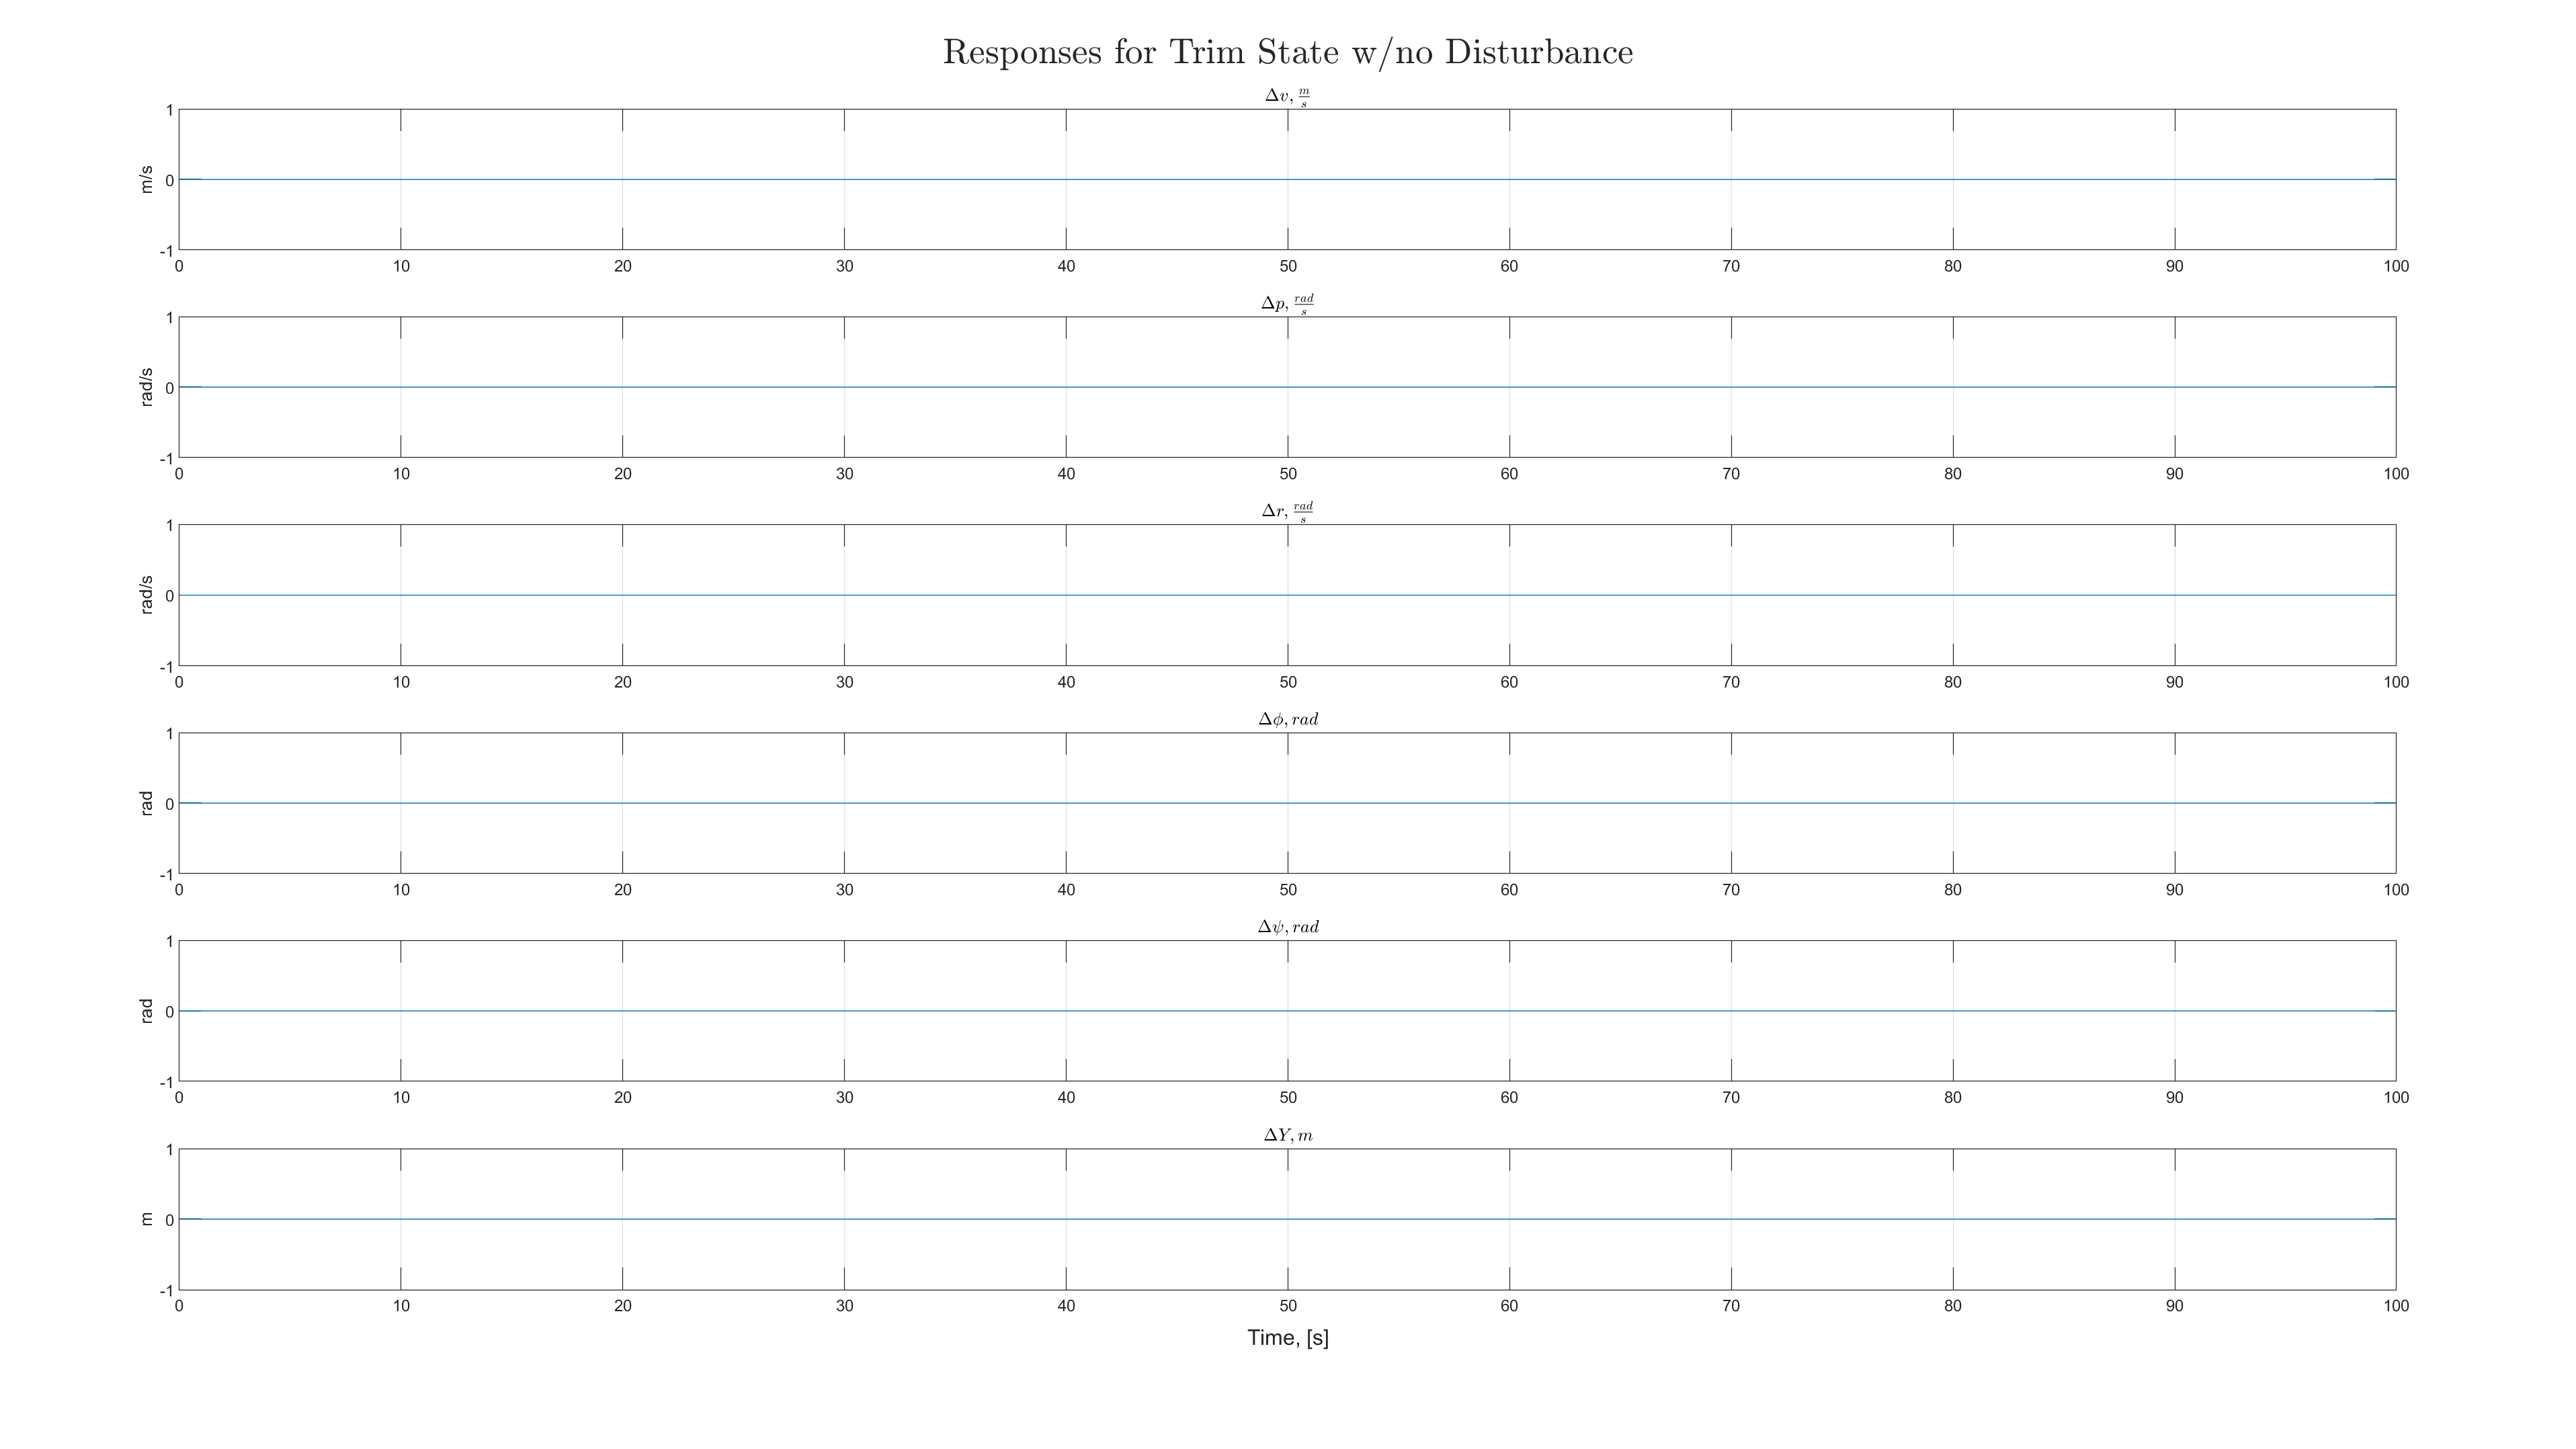

[t, y] = ode45(@(t, y) airplaneLatLin(t, y, Alat), tSpan, initialState);
plutter(t, y, 'Trim State w/no Disturbance')

t = 0;
y = 0; % reset so that we don't have to change variable names

We can clearly see that the values stay at 0!  Therefore, we are in equilibrium.

### b) Perturb initial states

#### Perturb v(0)

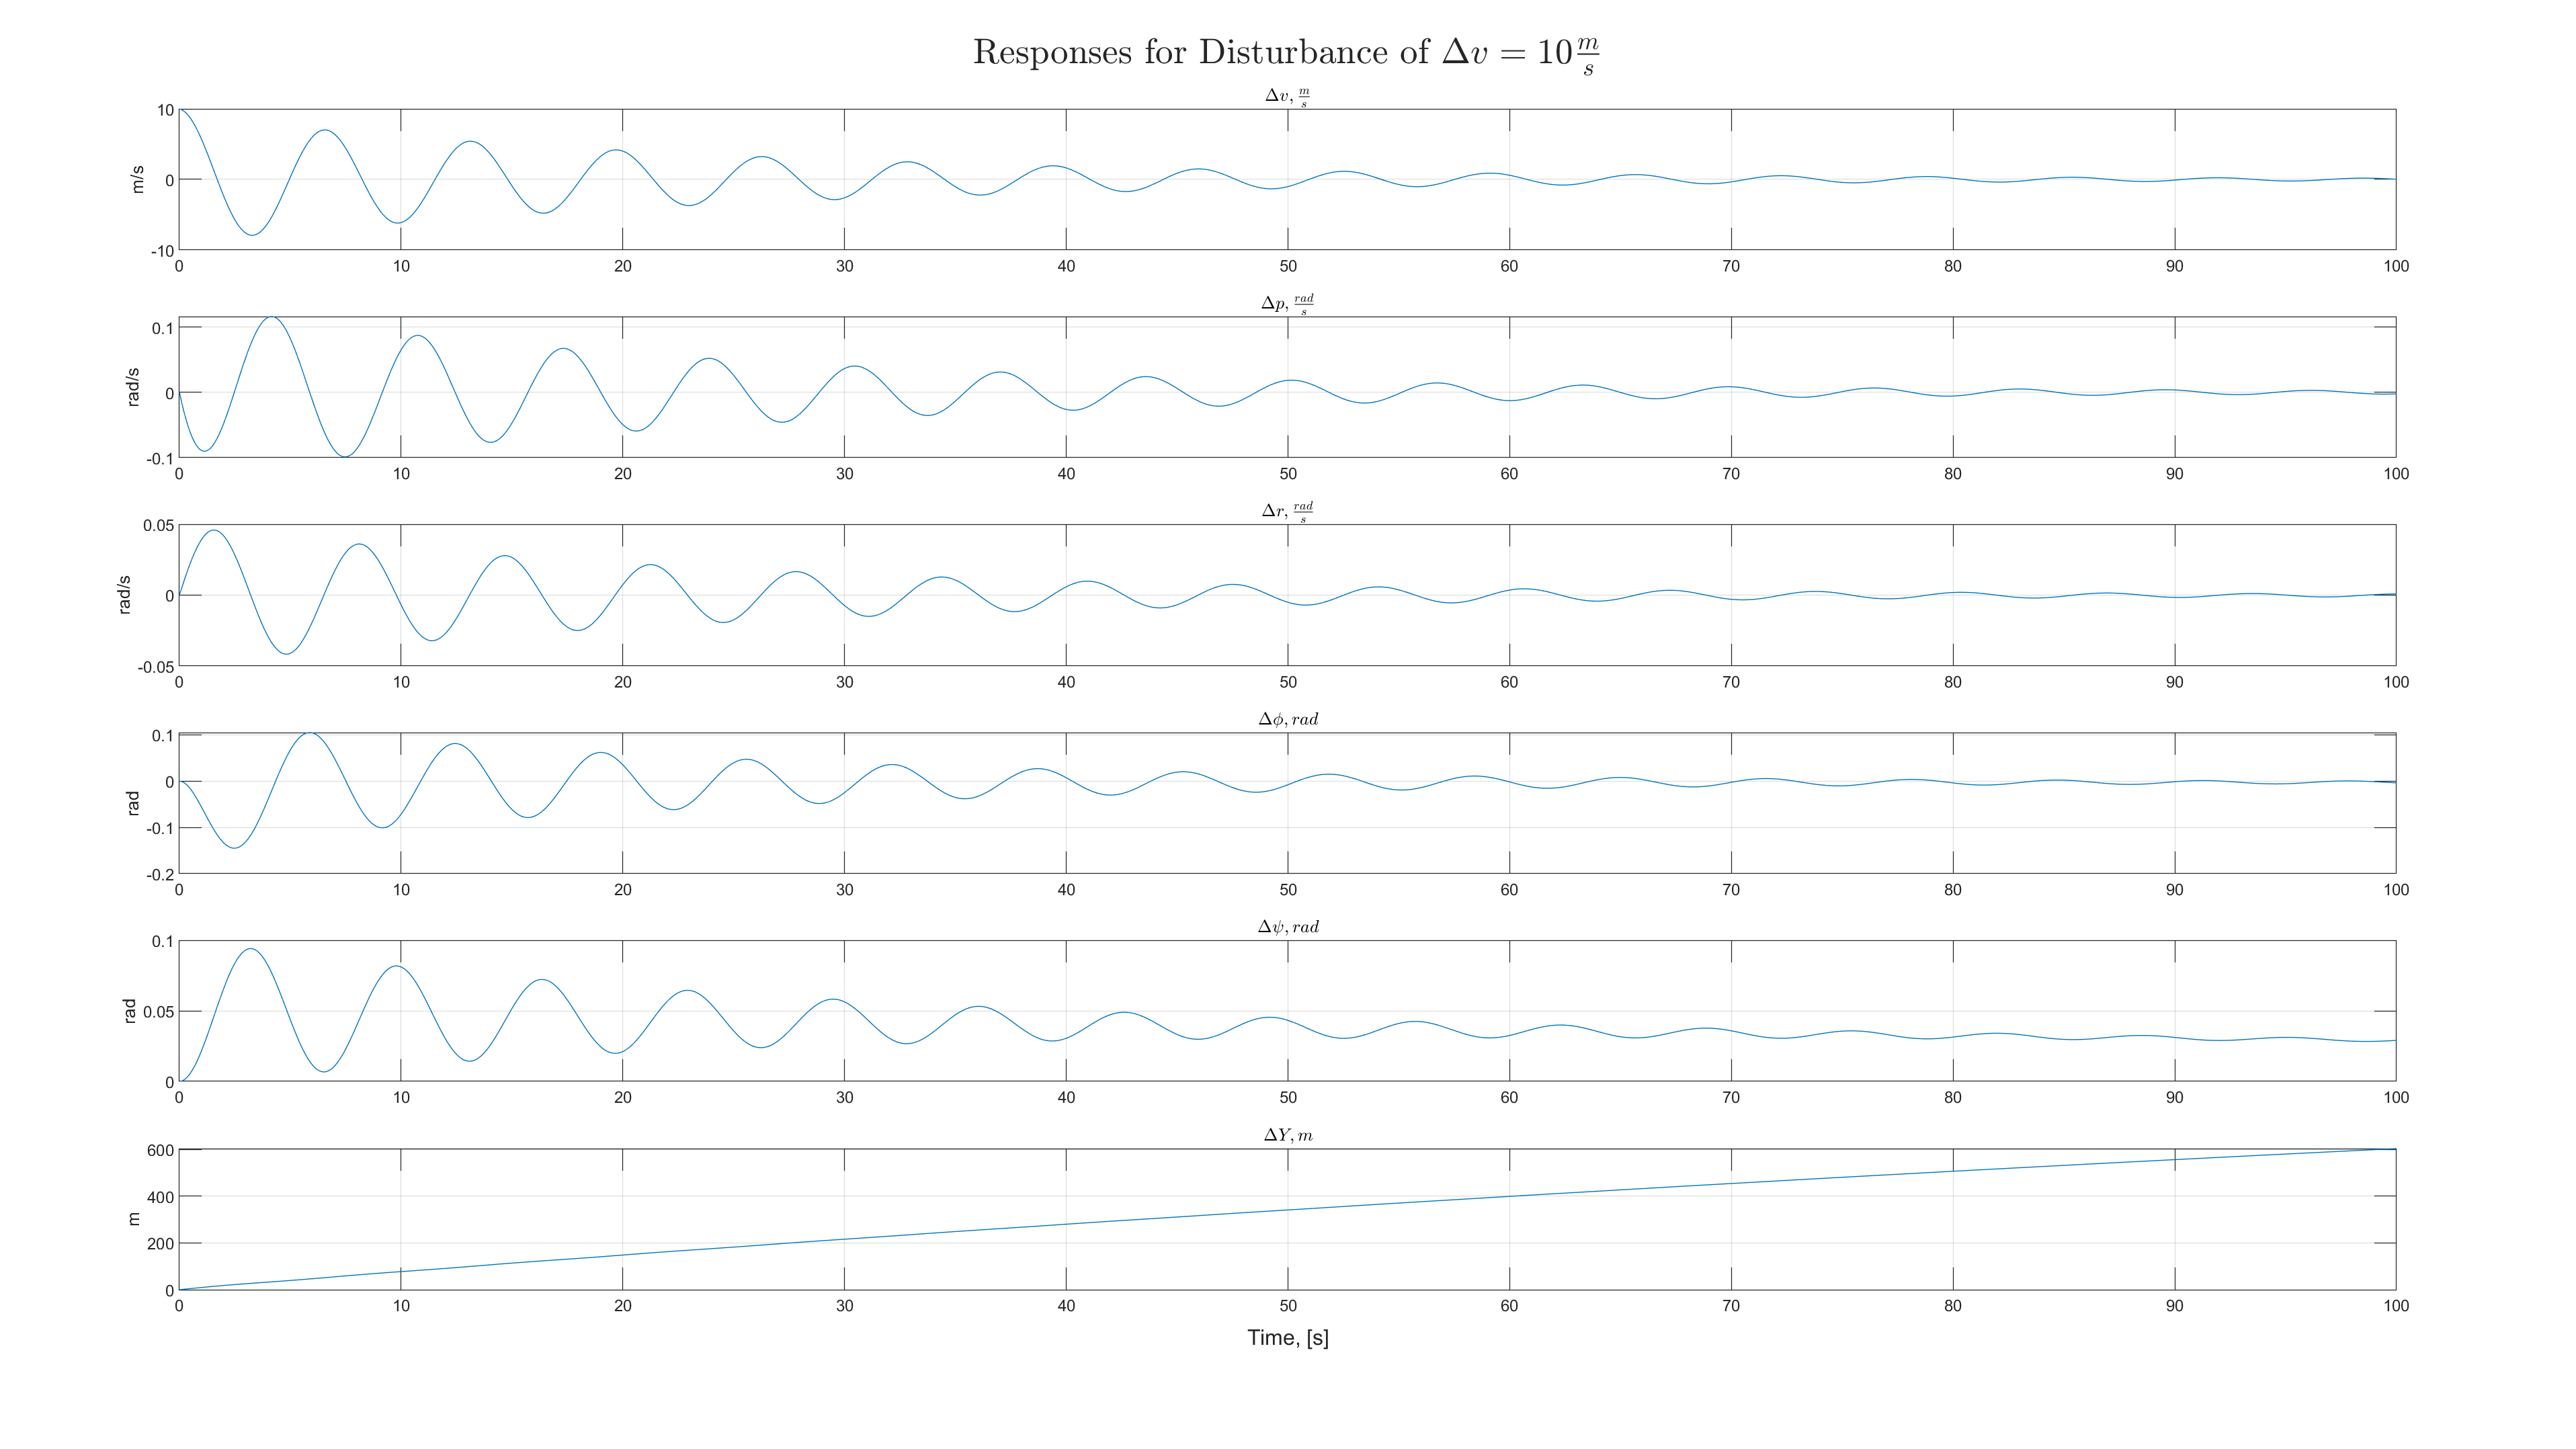

initialState(1) = 10; % m/s, perturb the v value

[t, y] = ode45(@(t, y) airplaneLatLin(t, y, Alat), tSpan, initialState);
plutter(t, y, 'Disturbance of $\Delta v = 10 \frac{m}{s}$')

t = 0;
y = 0; % reset so that we don't have to change variable names
initialState = initial;

#### Perturb p(0)

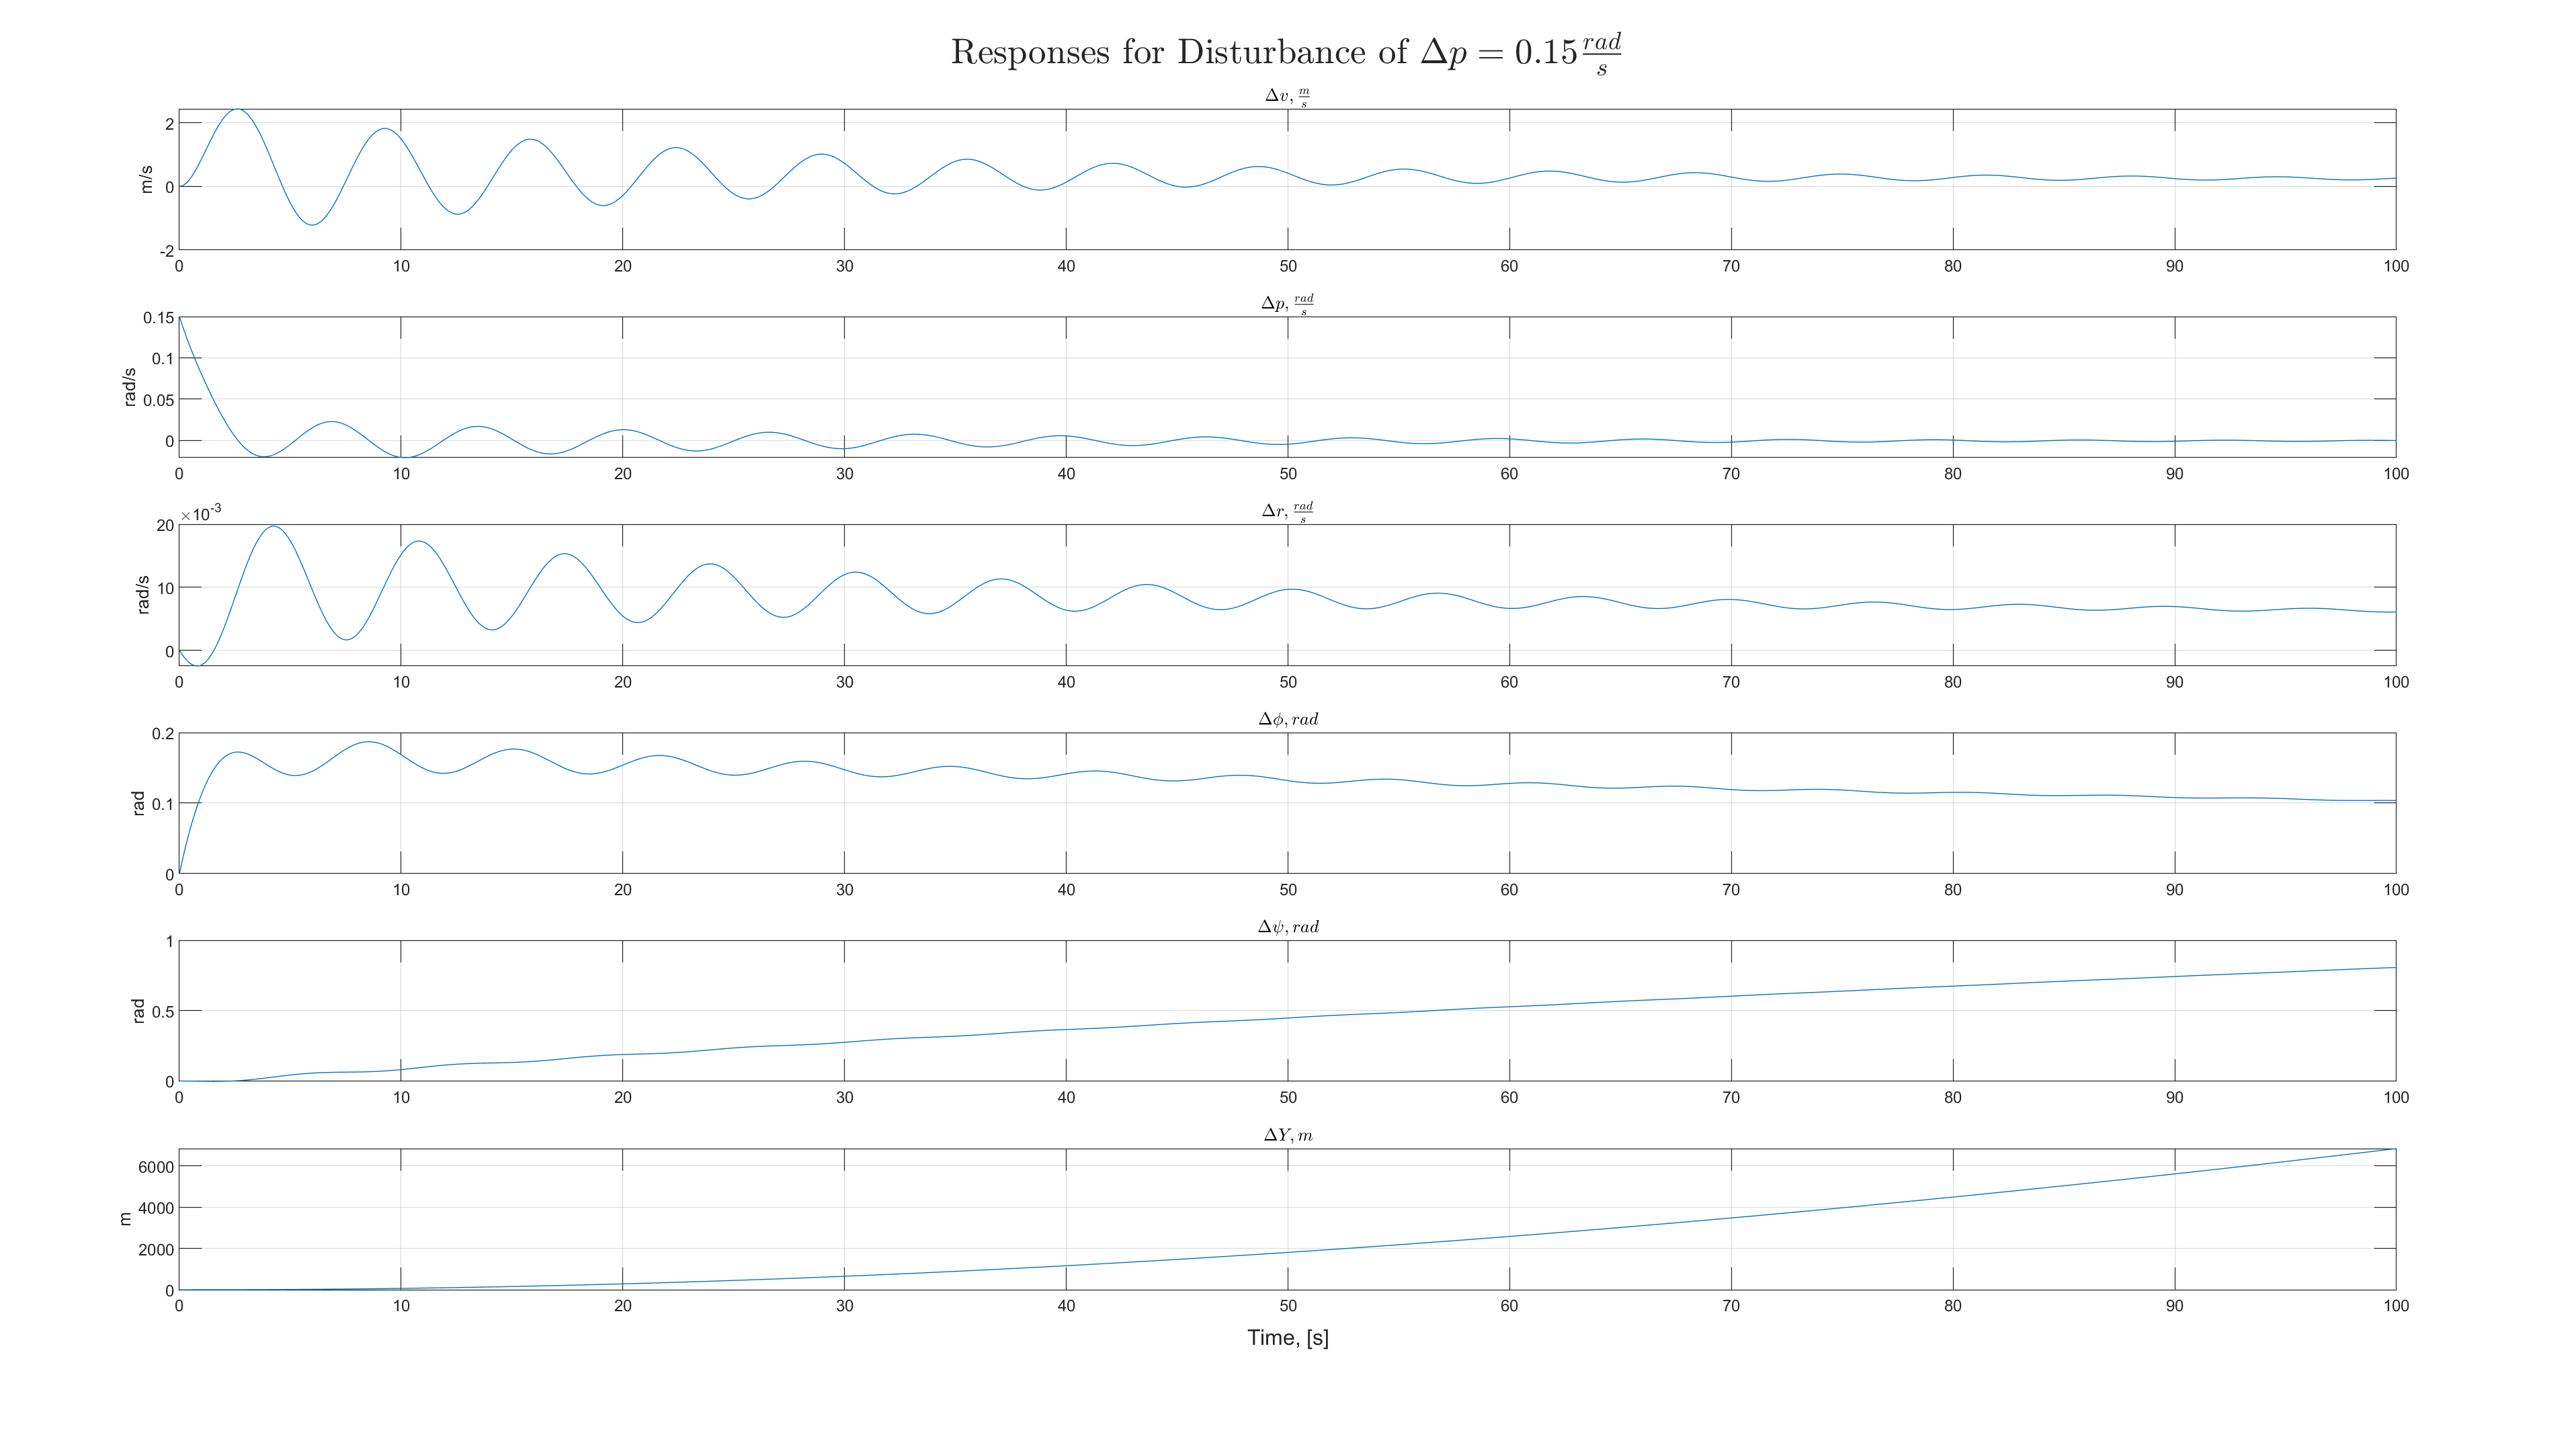

initialState(2) = 0.15; % rad/s

[t, y] = ode45(@(t, y) airplaneLatLin(t, y, Alat), tSpan, initialState);
plutter(t, y, 'Disturbance of $\Delta p = 0.15 \frac{rad}{s}$')

t = 0;
y = 0; % reset so that we don't have to change variable names
initialState = initial;

#### Change the whole initial state vector

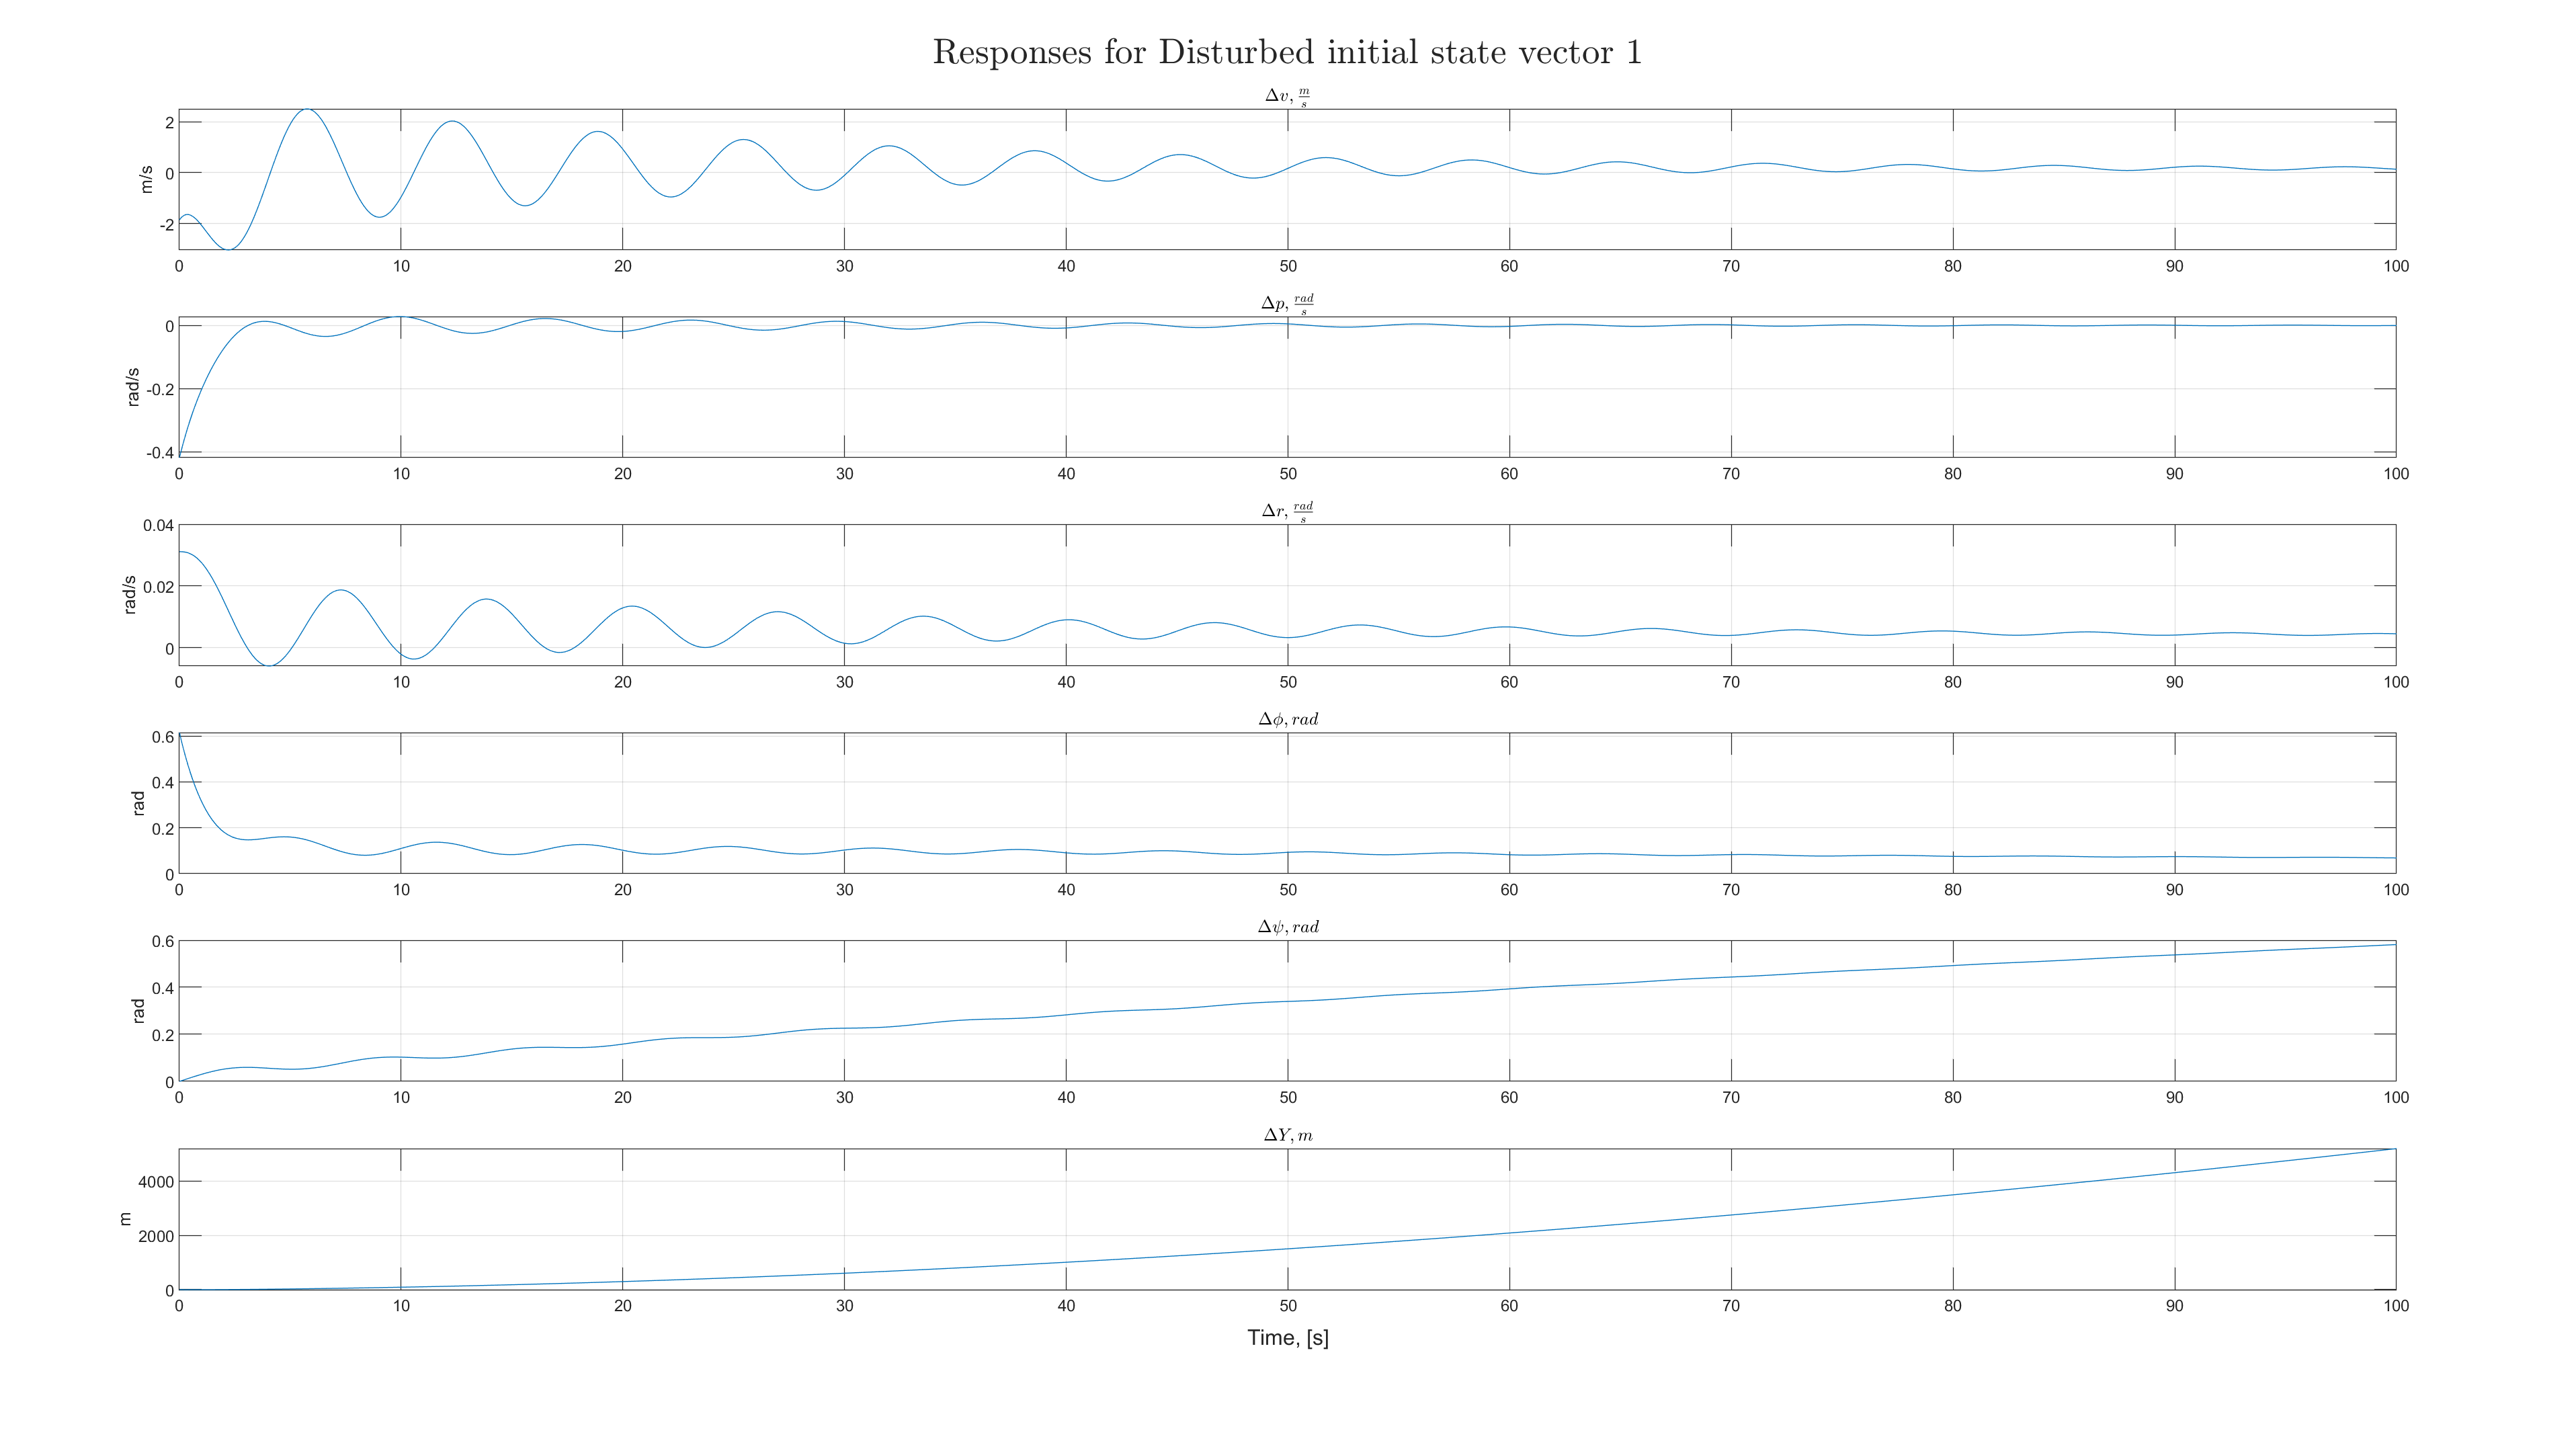

initialState(1:4) = [-1.8563;
                     -0.4185;
                     0.0311;
                     0.6148];
                 
[t, y] = ode45(@(t, y) airplaneLatLin(t, y, Alat), tSpan, initialState);
plutter(t, y, 'Disturbed initial state vector 1')

t = 0;
y = 0; % reset so that we don't have to change variable names
initialState = initial;

#### Do it again!

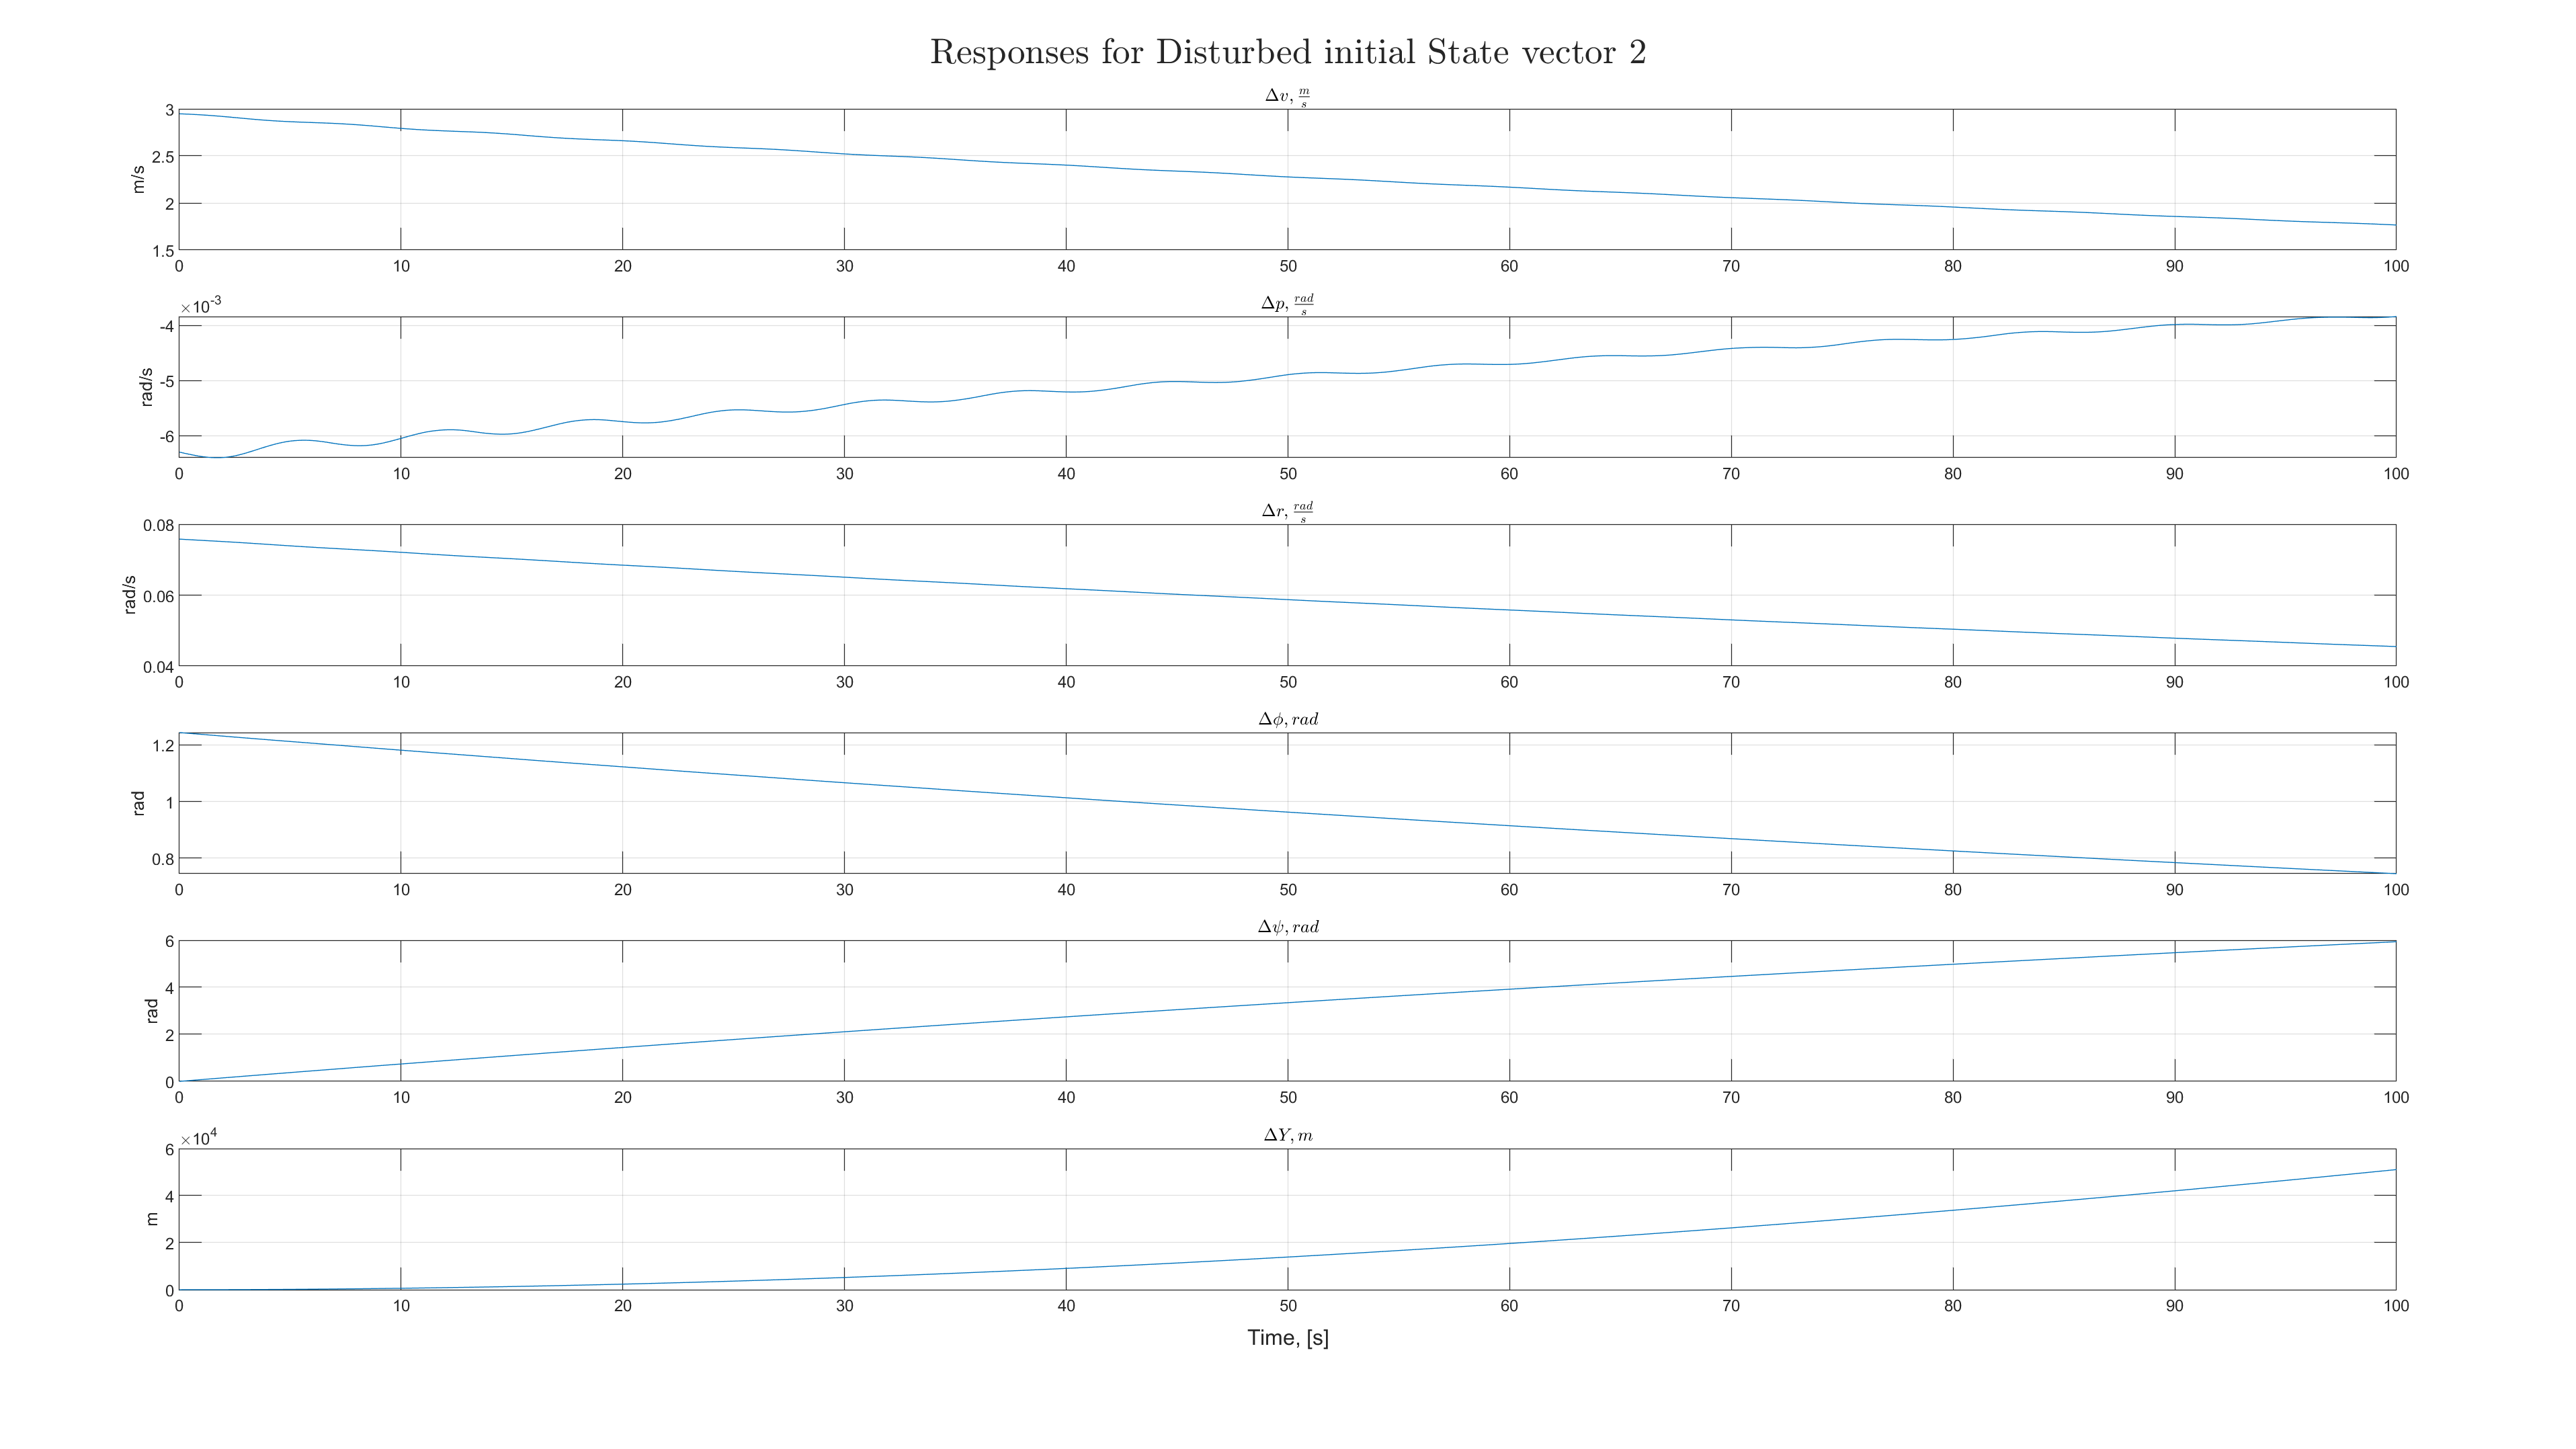

initialState(1:4) = [2.9477;
                     -0.0063;
                     0.0758;
                     1.2431];
                 
[t, y] = ode45(@(t, y) airplaneLatLin(t, y, Alat), tSpan, initialState);
plutter(t, y, 'Disturbed initial State vector 2')

t = 0;
y = 0; % reset so that we don't have to change variable names
initialState = initial;

Looking at the eigenvectors for each of the modes again,

Dutch1 = V(:,1)

Dutch1 =    0.9998 + 0.0000i
  -0.0094 + 0.0112i
   0.0005 - 0.0055i
   0.0121 + 0.0094i


Dutch2 = V(:,2)

Dutch2 =    0.9998 + 0.0000i
  -0.0094 - 0.0112i
   0.0005 + 0.0055i
   0.0121 - 0.0094i


Roll   = V(:,3)

Roll =    -0.9894
   -0.0881
    0.0029
    0.1153


Spiral = V(:,4)

Spiral =     0.9210
   -0.0020
    0.0237
    0.3889


we can see that some disturbances excite all of the modes, while some disturbances excite one or two modes over the others.  Going row by row:

Disturbances to $\Delta v$ will excite all three modes to roughly the same extent.

Disturbances to $\Delta p$ will excite primarily the Roll mode, followed by the Dutch Roll and then Spiral.

Disturbances to $\Delta r$ will excite the Spiral mode the most, with the Roll and Dutch Roll modes being excited roughly the same amount.

Finally, any disturbances to $\Delta \phi$ will excite the Spiral mode the most, closely followed by the Roll mode and the the Dutch Roll mode.

Looking at the plots for each disturbance case, we can see that these correspond with the behavior we see.